For the document network data, the inputs are two matrices. One is the M x N document-term matrix **X**, one is the citation/linkage matrix between M documents in M x M matrix **C**.

## #Initialize this script

clear classes

clear all 
close all
clc

rng(213);
datasets = {'cornell', 'texas', 'washington', 'wisconsin'};

## #Now loading relevent variables/matrices to the workspace

processing_data_id = 1;
load(['../Data/' datasets{processing_data_id} '.mat'], ...
    'C', 'X', 'webpage_ids', 'webpage_classnames');

## #Show the matrix structure

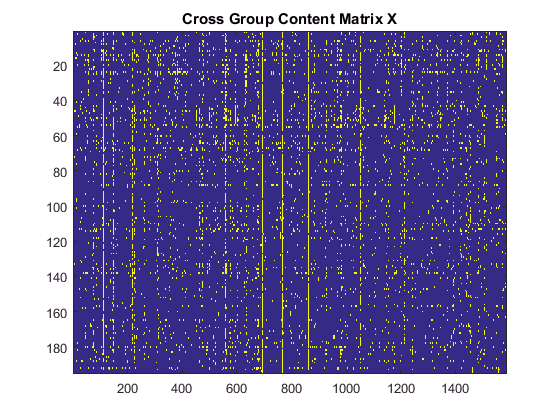

figure
imagesc(X);
title('Cross Group Content Matrix X');

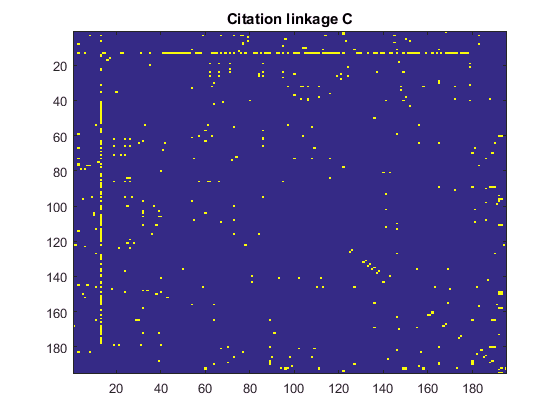


figure
C = C | C.';
imagesc(C);
title('Citation linkage C');

## #Split the data into training and testing sets

% setting the training sampling rate
training_sampling_ratio = 0.001;    % take this percentage links as positive traning links


M = size(C, 1);
total_links = M * (M - 1) / 2;
nb_training_samples = floor(training_sampling_ratio * total_links);

% gettting the indexes of the linkages
C = triu(C);
C = C - diag(diag(C));
[row_idx, column_idx] = find(C > 0);
nb_testing_samples = floor(length(row_idx) - nb_training_samples);
disp(['known linkages: #' num2str(length(row_idx)) ' ' num2str(100*length(row_idx)/total_links) '%']);

known linkages: #283 1.4962%


disp(['training sets: #' num2str(nb_training_samples) ' ' num2str(100*nb_training_samples/total_links) '%']);

training sets: #18 0.095163%


disp(['testing sets: #' num2str(nb_testing_samples) ' ' num2str(100*nb_testing_samples/total_links) '%']);

testing sets: #265 1.401%



% random sampling step
idx_permutation = randperm(length(row_idx));
idx_train = idx_permutation(1 : nb_training_samples);
idx_test = idx_permutation(nb_training_samples : end);

C = sparse(row_idx(idx_train), column_idx(idx_train), ...
            ones(nb_training_samples, 1), M, M);    % this linkage matrix is for traning

row_idx_test = row_idx(idx_test);
column_idx_test = column_idx(idx_test);

% post processing
C = C | C.';

## #save the current data file

save([datasets{processing_data_id} '_split.mat'], 'C', 'X', 'webpage_ids', 'webpage_classnames', 'row_idx_test', 'column_idx_test');